rng(1);

SNR = -20:0.1:20;
a = 1;
number_of_vectors = size(SNR);
number_of_vectors = number_of_vectors(1,2);
length_of_vetor = 1e3;
x = randi([1,2],number_of_vectors,length_of_vetor);
x(x==2) = -1;

for i=1:100
N0_h = ones(1,number_of_vectors);
h = complex_normal(number_of_vectors,N0_h,length_of_vetor);
% h = mean(h,1);
% h = repmat(h,size(x,1),1);
N0_w = (a^2)./(10.^(SNR/10));
w = complex_normal(number_of_vectors,N0_w,length_of_vetor);
[y, Equalized_y, err_prob(:,i)] = channel(x,h,w);
end

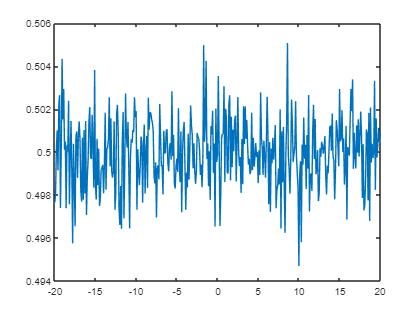

err_probab = mean(err_prob,2);
plot(SNR,err_probab);

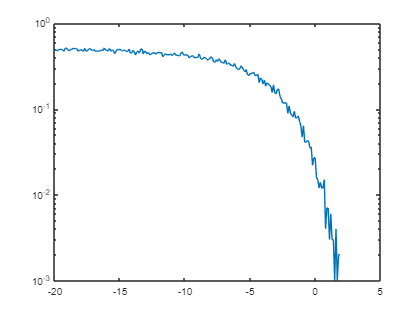

for i=1:100
h = ones(number_of_vectors,length_of_vetor);
[y, Equalized_y, err_prob(:,i)] = channel(x,h,w);
end
err_probab = mean(err_prob,2);
semilogy(SNR,err_probab)

Question2.

x = randi([0,1],number_of_vectors,length_of_vetor);

transmited_x = convert_to_transmited(x);
length_of_vetor = size(transmited_x,2);

for i=1:100
N0_h = ones(1,number_of_vectors);
h = complex_normal(number_of_vectors,N0_h,length_of_vetor);
N0_w = (a^2)./(10.^(SNR/10));
w = complex_normal(number_of_vectors,N0_w,length_of_vetor);

[y, Equalized_y, err_prob_two(:,i)] = channeltwo(x,transmited_x,h,w);
end

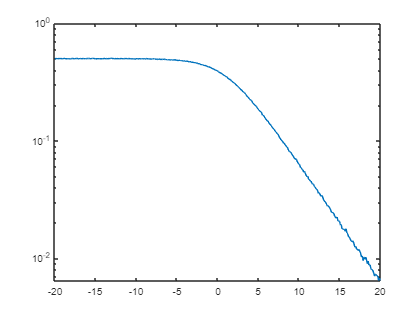

err_probab_two = mean(err_prob_two,2);
semilogy(SNR,err_probab_two)

Question3.

length_of_vetor = 1e3;
x = randi([1,2],number_of_vectors,length_of_vetor);
x(x==2) = -1;

for i=1:100
N0_h = ones(1,number_of_vectors);
h = complex_normal(number_of_vectors,N0_h,length_of_vetor);
% h = mean(h,1);
% h = repmat(h,size(x,1),1);
N0_w = (a^2)./(10.^(SNR/10));
w = complex_normal(number_of_vectors,N0_w,length_of_vetor);
[y, Equalized_y, err_prob_three(:,i)] = channelthree(x,h,w);
end

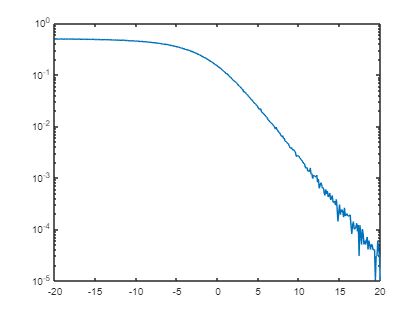

err_probab_three = mean(err_prob_three,2);
semilogy(SNR,err_probab_three);

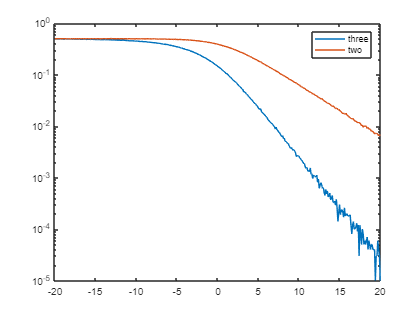

figure
semilogy(SNR,err_probab_three)
hold on
semilogy(SNR,err_probab_two)
legend("three","two")
hold off

Question4.

x = randi([0,1],number_of_vectors,length_of_vetor);
transmited_x = convert_to_transmited_four(x);
length_of_vetor = size(transmited_x,2);

for i=1:100
N0_h = ones(1,number_of_vectors);
h = complex_normal(number_of_vectors,N0_h,length_of_vetor);
N0_w = (a^2)./(10.^(SNR/10));
w = complex_normal(number_of_vectors,N0_w,length_of_vetor);
[y, Equalized_y, err_prob_four(:,i)] = channelfour(x,transmited_x,h,w);
end

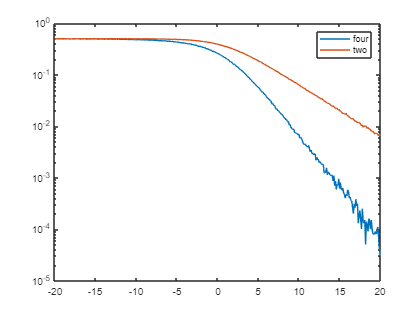

err_probab_four = mean(err_prob_four,2);
figure
semilogy(SNR,err_probab_four);
hold on
semilogy(SNR,err_probab_two)
legend("four","two")
hold off

Question5.

length_of_vetor = 1e3;
x = randi([1,2],number_of_vectors,length_of_vetor);
x(x==2) = -1;
L=5;
for i=1:100
    for j=1:L
        N0_h = ones(1,number_of_vectors);
        h = complex_normal(1,N0_h,length_of_vetor);
        h = repmat(h,number_of_vectors,1);

        N0_w = (a^2)./(10.^(SNR/10));
        w = complex_normal(number_of_vectors,N0_w,length_of_vetor);
        [y(:,:,j)] = channelfive(x,h,w);
    end
    final_Diversity_detected = sum(y,3);
    Equalized_y = final_Diversity_detected;
    Equalized_y(real(Equalized_y)>0) = 1;
    Equalized_y(real(Equalized_y)<0) = -1;
    temp = x-Equalized_y;
    err_prob_five(:,i) = error_probability(temp);
end

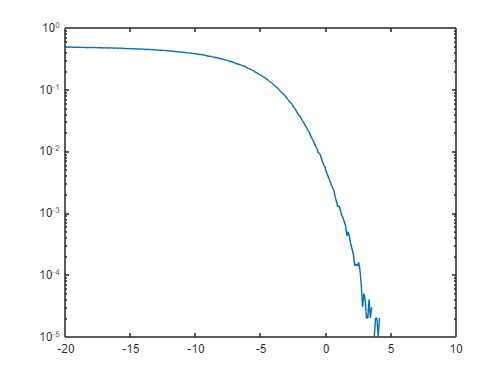

err_probab_five = mean(err_prob_five,2);
semilogy(SNR,err_probab_five);

Question6.

length_of_vetor = 1e3;
x = randi([1,2],number_of_vectors,length_of_vetor);
x(x==2) = -1;

for i=1:100
N0_h = ones(1,number_of_vectors);

h1 = complex_normal(1,N0_h,length_of_vetor);
%h1 = repmat(h1,number_of_vectors,1);

h2 = complex_normal(1,N0_h,length_of_vetor);
%h2 = repmat(h2,number_of_vectors,1);


N0_w = (a^2)./(10.^(SNR/10));
w1 = complex_normal(number_of_vectors,N0_w,length_of_vetor);
w2 = complex_normal(number_of_vectors,N0_w,length_of_vetor);

[y, Equalized_y, err_prob_six(:,i)] = channelsix(x,h1,h2,w1,w2);
end

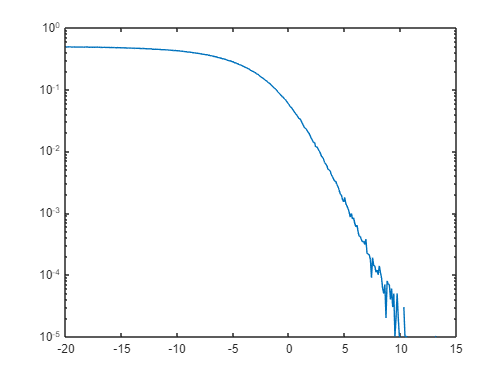

err_probab_six = mean(err_prob_six,2);
semilogy(SNR,err_probab_six);

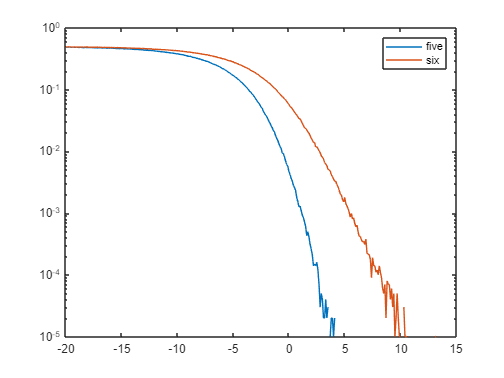

figure
semilogy(SNR,err_probab_five);
hold on
semilogy(SNR,err_probab_six)
legend("five","six")
hold off

Functions.

function Q = complex_normal(number_of_vectors,N0,length_of_vetor) 
Q = zeros(number_of_vectors,length_of_vetor);
for i=1:number_of_vectors
    Q_re = N0(i)/2*randn(1,length_of_vetor);
    Q_im = N0(i)/2*randn(1,length_of_vetor);
    Q(i,:) = Q_re + 1i*Q_im;
end
end

function err_prob = error_probability(temp)
s = size(temp);
err_prob = zeros(s(1,1),1);
for i=1:s(1,1)
    err_prob(i,1) = nnz(temp(i,:))/s(1,2);
end
end

function [y, Equalized_y, err_prob] = channel(x,h,w)
y = x.*h + w;
Equalized_y = y;
Equalized_y(real(Equalized_y)>0) = 1;
Equalized_y(real(Equalized_y)<0) = -1;
temp = x-Equalized_y;
err_prob = error_probability(temp);
end

function [y, Equalized_y, err_prob] = channeltwo(x,transmited_x,h,w)
y = transmited_x.*h + w;

for i=1:size(y,1)
    temp = [];
    for j=1:2:size(y,2)
        if abs(real(y(i,j)))<abs(real(y(i,j+1)))
            temp=[temp,0];
        else
            temp=[temp,1];
        end
    end
    Equalized_y(i,:) = temp;
end


temp1 = x-Equalized_y;
err_prob = error_probability(temp1);

end

function [y, Equalized_y, err_prob] = channelthree(x,h,w)
y = x.*h + w;
Equalized_y = y;

for i=1:size(x,1)
Equalized_y(i,:) = Equalized_y(i,:).*(conj(h(i,:))./abs(h(i,:)));
end

Equalized_y(real(Equalized_y)>0) = 1;
Equalized_y(real(Equalized_y)<0) = -1;

temp = x-Equalized_y;
err_prob = error_probability(temp);

end


function [y, Equalized_y, err_prob] = channelfour(x,transmited_x,h,w)

y = transmited_x.*h + w;

for i=1:size(x,1)
y(i,:) = y(i,:).*(conj(h(i,:))./abs(h(i,:)));
end

for i=1:size(y,1)
    temp = [];
    for j=1:size(y,2)
        if (angle(y(i,j)) > -pi/4 && angle(y(i,j)) < pi/4)
                  temp=[temp,[0,0]];
        end
        if (angle(y(i,j)) > pi/4 && angle(y(i,j)) < 3*pi/4)
                  temp=[temp,[0,1]];
        end
        if (angle(y(i,j)) < -3*pi/4 || angle(y(i,j)) > 3*pi/4)
                 temp=[temp,[1,0]];
        end
        if (angle(y(i,j)) > -3*pi/4 && angle(y(i,j)) < -pi/4)
                  temp=[temp,[1,1]];
        end
    end
    Equalized_y(i,:) = temp;
end

temp1 = x-Equalized_y;
err_prob = error_probability(temp1);

end

function [y] = channelfive(x,h,w)
y = x.*h + w;
for i=1:size(y,1)
        y(i,:) = y(i,:).*(conj(h(i,:))/sum(abs(h(i,:))));
end

end

function [y, Equalized_y, err_prob] = channelsix(x,h1,h2,w1,w2)

for i=1:size(x,1)
    for j=1:2:size(x,2)
        tempp = [h1(j),h2(j)]*[x(i,j),-1*conj(x(i,j+1));x(i,j+1),conj(x(i,j))]+[w1(i,j),w2(i,j)];
        y(i,j) = tempp(1);
        y(i,j+1) = tempp(2);
    end
end

for i=1:size(y,1)
    for j=1:2:size(x,2)
        n1(i,j) = conj(h1(j))*w1(i,j)+h2(j).*conj(w2(i,j));
        n2(i,j) = conj(h2(j))*w1(i,j)-h1(j).*conj(w2(i,j));
        Equalized_y(i,j) = (abs(h1(j))^2 + abs(h2(j))^2)* x(i,j) + n1(i,j);
        Equalized_y(i,j+1) = (abs(h1(j))^2 + abs(h2(j))^2)* x(i,j+1) + n2(i,j);
    end
end

Equalized_y(real(Equalized_y)>0) = 1;
Equalized_y(real(Equalized_y)<0) = -1;

temp = x-Equalized_y;
err_prob = error_probability(temp);

end


function transmited_x = convert_to_transmited(x)

for i=1:size(x,1)
    temp = [];
    for j=1:size(x,2)
        if x(i,j)==1
            temp=[temp,[1,0]];
        else
            temp=[temp,[0,1]];
        end
    end
    transmited_x(i,:) = temp;
end

end

function transmited_x = convert_to_transmited_four(x)

for i=1:size(x,1)
    temp = [];
    for j=1:2:size(x,2)
        if x(i,j) == 0
            if x(i,j+1)==1
                temp=[temp,1i];
            else
                temp=[temp,1];
            end
        else
            if x(i,j+1)==1
                temp=[temp,-1i];
            else
                temp=[temp,-1];
            end
        end
    end
    transmited_x(i,:) = temp;
end
end